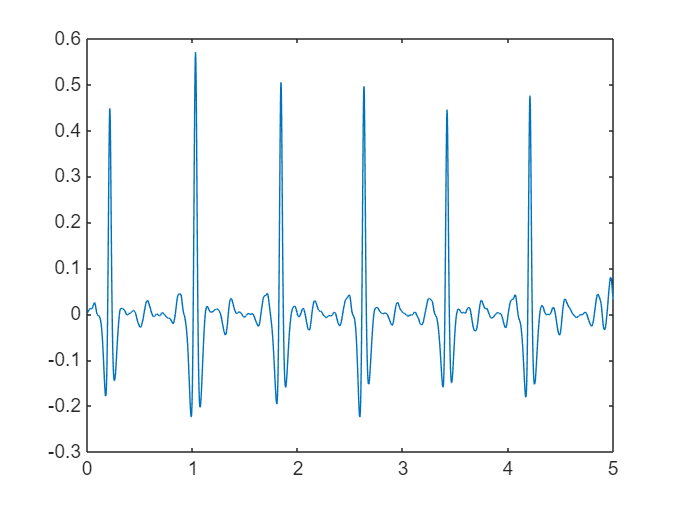

clc;
close all;
clear all;

[tm,signal,fs,labels] = rdmat('100m');
ch1 = signal(:,1);
ch2 = signal(:,2);
t = tm(1:1800);
s1 = ch1(1:1800);
s2 = ch2(1:1800);

x = s1;
ecg_signal = x;
% Ensure the input signal is a column vector
    ecg_signal = ecg_signal(:);

    % Length of the input signal
    N = length(ecg_signal);

    % Initialize variables
    r_peaks = []; % Store detected R-peak locations

    % Bandpass Filter Design (5-15 Hz)
    [b_band, a_band] = butter(1, [5 15] / (fs / 2), 'bandpass');
    filtered_ecg = filtfilt(b_band, a_band, ecg_signal);
    plot(t,filtered_ecg);

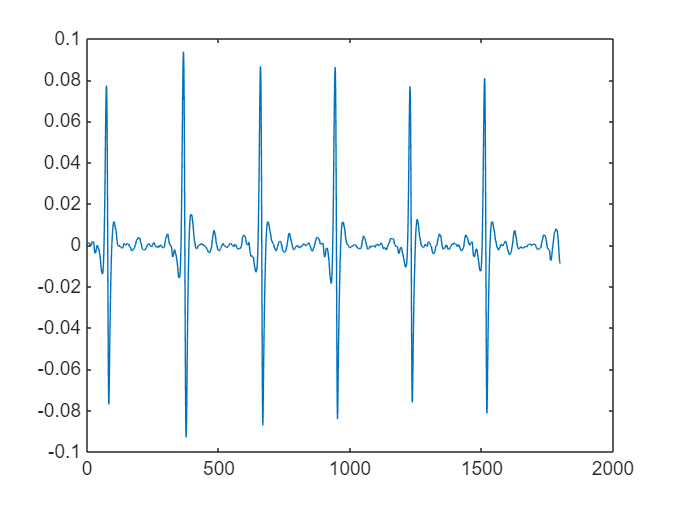


    % Differentiation
    diff_ecg = diff(filtered_ecg);
    plot(diff_ecg);

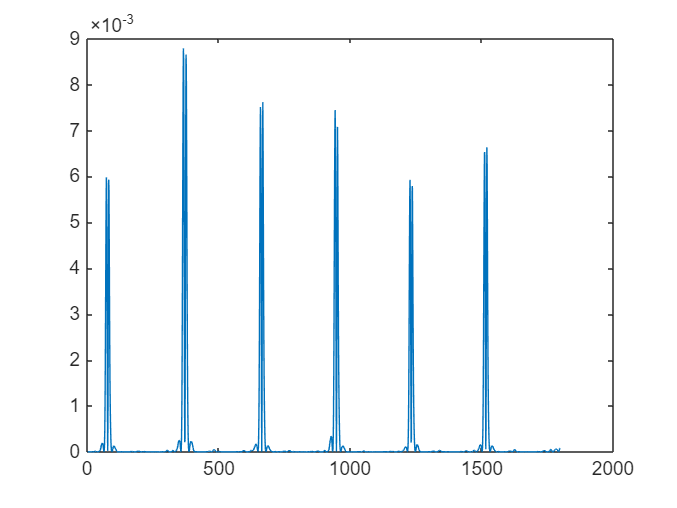


    % Squaring
    squared_ecg = diff_ecg .^ 2;
    plot(squared_ecg);

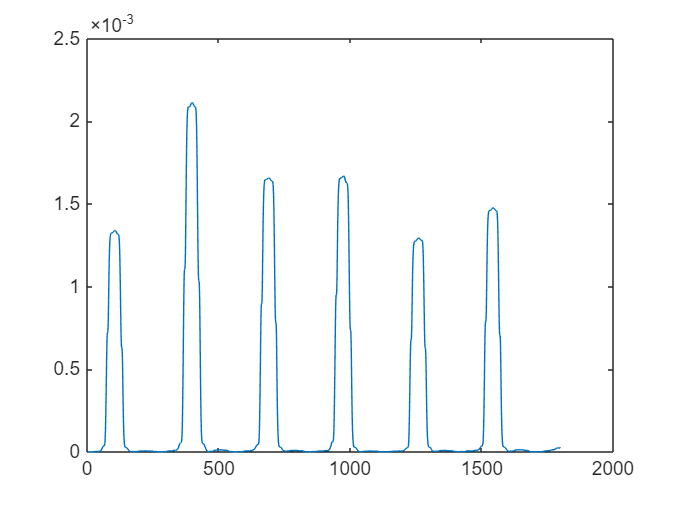


    % Moving Window Integration
    window_size = round(0.150 * fs); % 150 ms window
    y = filter(ones(1, window_size) / window_size, 1, squared_ecg);
    plot(y);

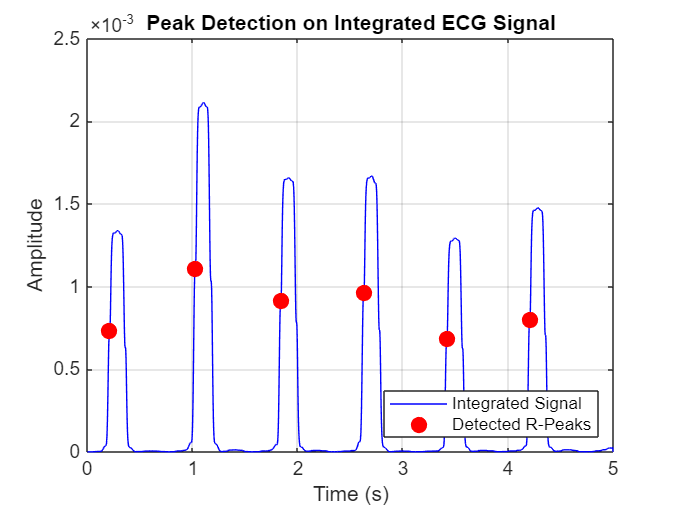


    % Threshold Initialization
    threshold = 0.6 * max(y); % Initial threshold
    SPKI = threshold;  % Initial signal peak estimate
    NPKI = 0.5 * threshold; % Initial noise peak estimate

    % Peak Detection
    i = 1;
    while i <= N - window_size
        if y(i) > threshold
            % Search back for the corresponding peak in the original signal
            [~, peak_index] = max(ecg_signal(i:i + window_size - 1));
            r_peak = i + peak_index - 1;
            r_peaks = [r_peaks; r_peak];

            % Update signal peak estimate
            SPKI = 0.125 * y(i) + 0.875 * SPKI;

            % Update threshold
            threshold = NPKI + 0.25 * (SPKI - NPKI);

            % Skip refractory period (200 ms)
            i = i + round(0.2 * fs);
        else
            % Update noise peak estimate
            NPKI = 0.125 * y(i) + 0.875 * NPKI;

            % Update threshold
            threshold = NPKI + 0.25 * (SPKI - NPKI);

            i = i + 1;
        end
    end

    % Compute Heart Rate
    if length(r_peaks) > 1
        rr_intervals = diff(r_peaks) / fs;
        heart_rate = 60 ./ rr_intervals; % Convert RR intervals to BPM
    else
        heart_rate = [];
    end
y = [y; 0]';  % For column vector (vertical)

% Plot Integrated ECG Signal and Detected Peaks in subplot (not a new figure)
%subplot(3,3,7);
plot(t, y, 'b'); % Plot integrated ECG signal
hold on;
plot(t(r_peaks), y(r_peaks), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Plot detected peaks
xlabel('Time (s)');
ylabel('Amplitude');
title('Peak Detection on Integrated ECG Signal');
legend('Integrated Signal', 'Detected R-Peaks', 'Location', 'southeast');
grid on;
hold off;

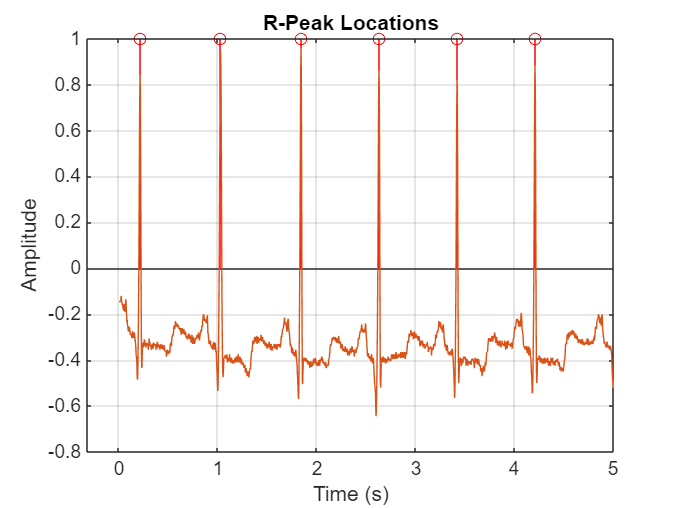


% Final plot: Peaks visualization
%subplot(3,3,8);
z = ones(size(y)); % Ensure z matches the signal length
stem(t(r_peaks), z(r_peaks), 'r');
hold on;
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('R-Peak Locations');
grid on;
hold off;